# 予測勝率の式の変換

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

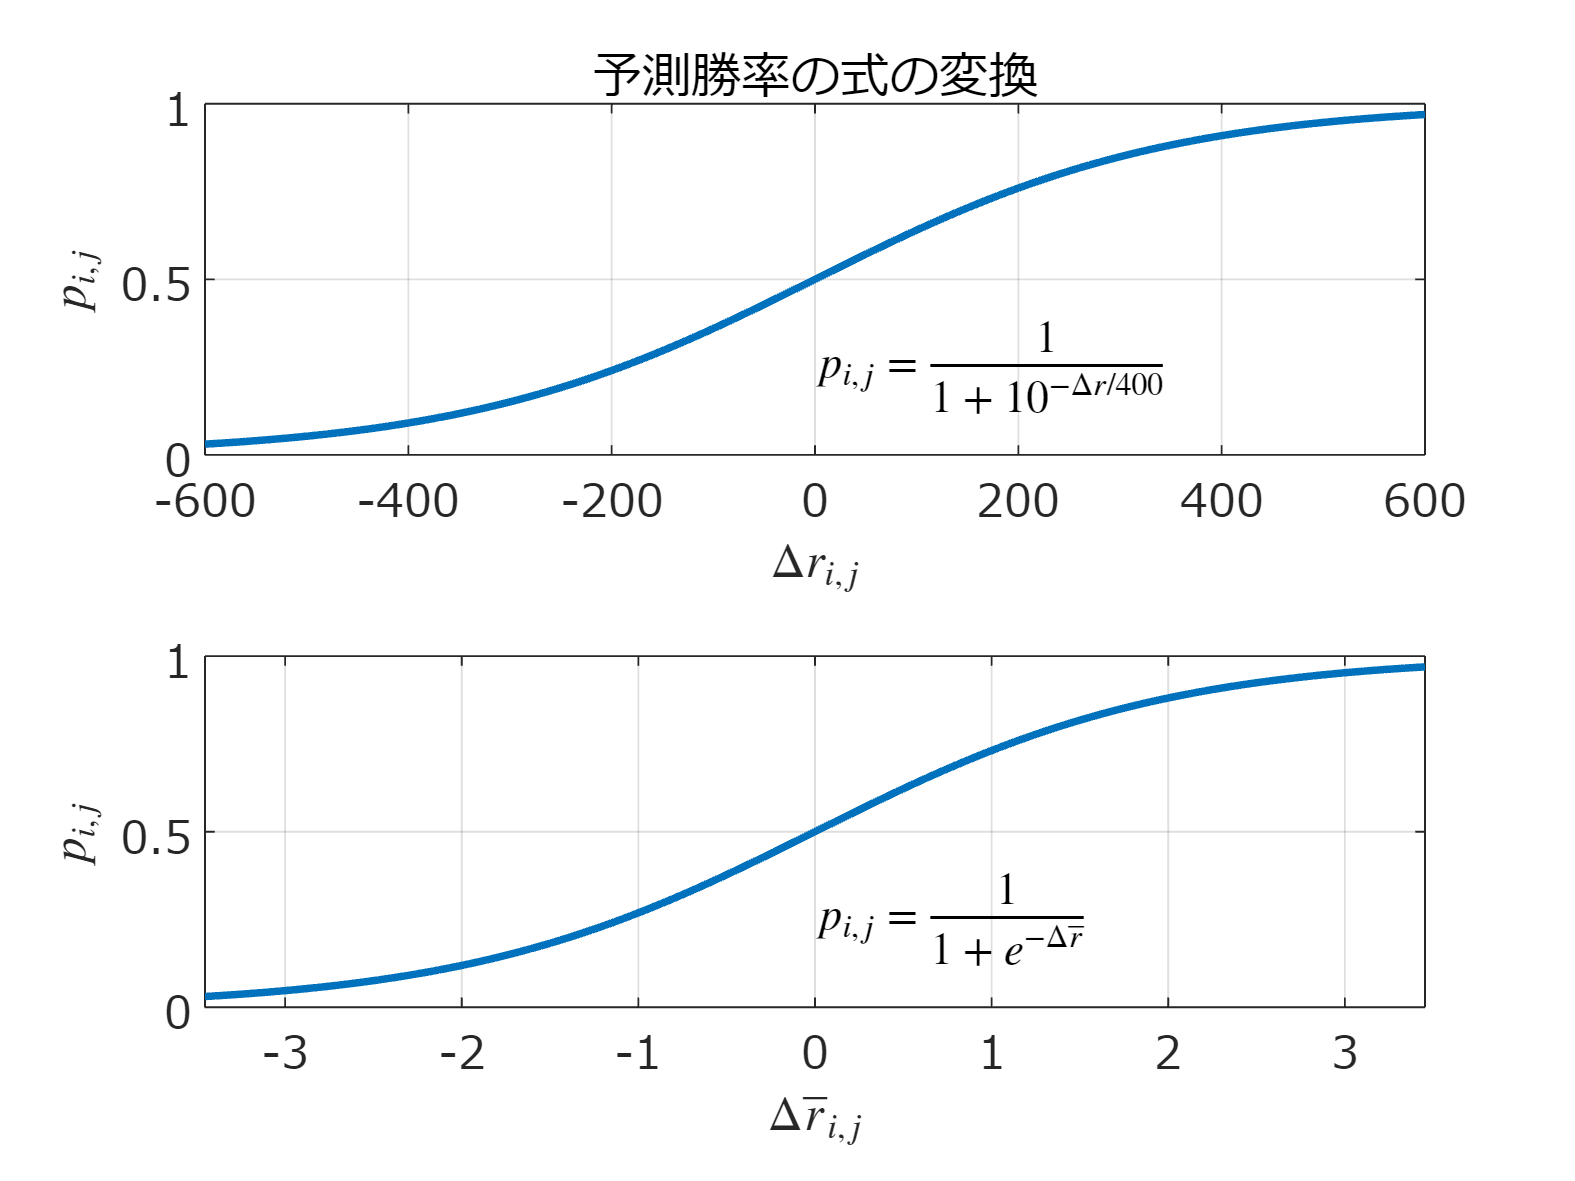

clear;clc;close all
figure
tiledlayout(2,1);
nexttile
dr=-600:10:600;
p=1./(1+10.^(-dr/400));
plot(dr,p,'LineWidth',2);
grid on;set(gca,'fontname','メイリオ','FontSize',12);
xlabel('$\Delta r_{i,j}$','Interpreter','latex');
ylabel('$p_{i,j}$','Interpreter','latex');
xlim([-600 600]);
text(0,0.25,'$p_{i,j}=\frac{1}{1+10^{-\Delta r/400}}$',...
    'Interpreter','latex','FontSize',12)
title('予測勝率の式の変換','fontname','メイリオ')

nexttile
dr=dr*log(10)/400;
p=1./(1+exp(-dr));
plot(dr,p,'LineWidth',2);
grid on;set(gca,'fontname','メイリオ','FontSize',12);
xlabel('$\Delta \overline{r}_{i,j}$','Interpreter','latex');
ylabel('$p_{i,j}$','Interpreter','latex');
xlim([-600 600]*log(10)/400);
text(0,0.25,'$p_{i,j}=\frac{1}{1+e^{-\Delta \overline{r}}}$',...
    'Interpreter','latex','FontSize',12)
exportgraphics(gcf, 'fig_sigmoidConv.pdf');